load measurement.mat;
load dataset.mat;

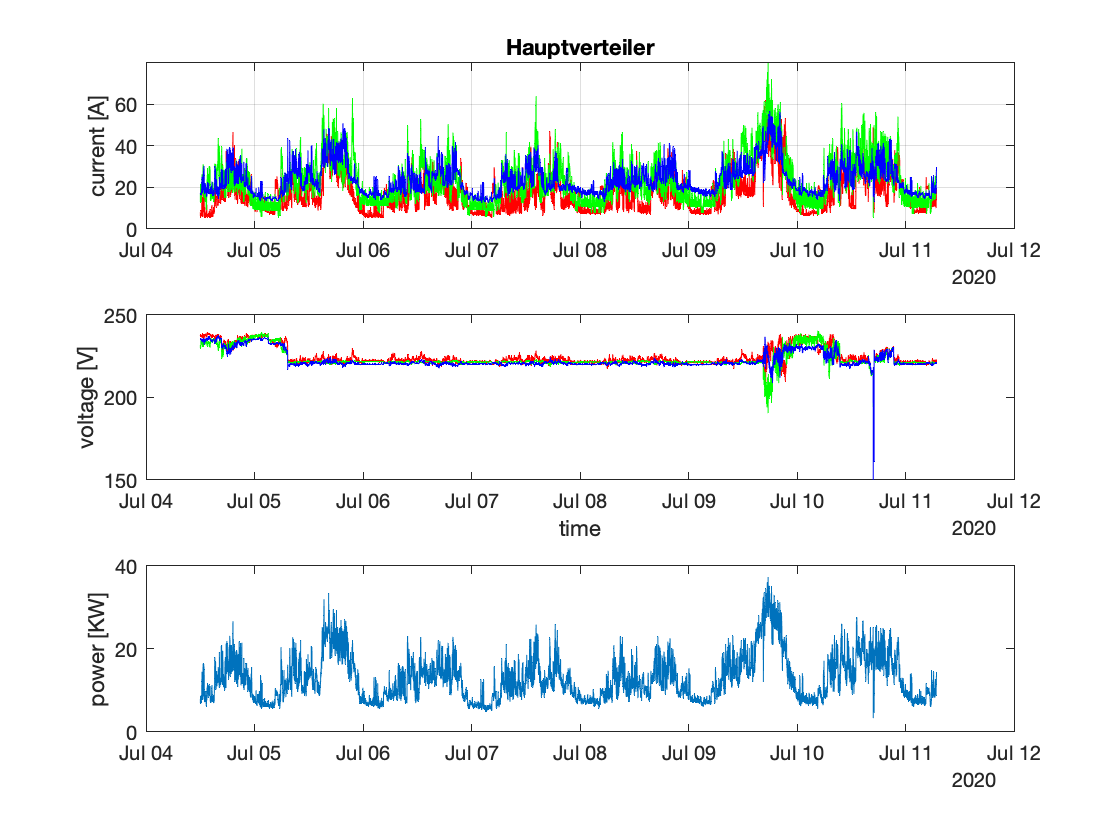

%% show Overview
f11 = f_analyze_Overview(PEL1, "Hauptverteiler");

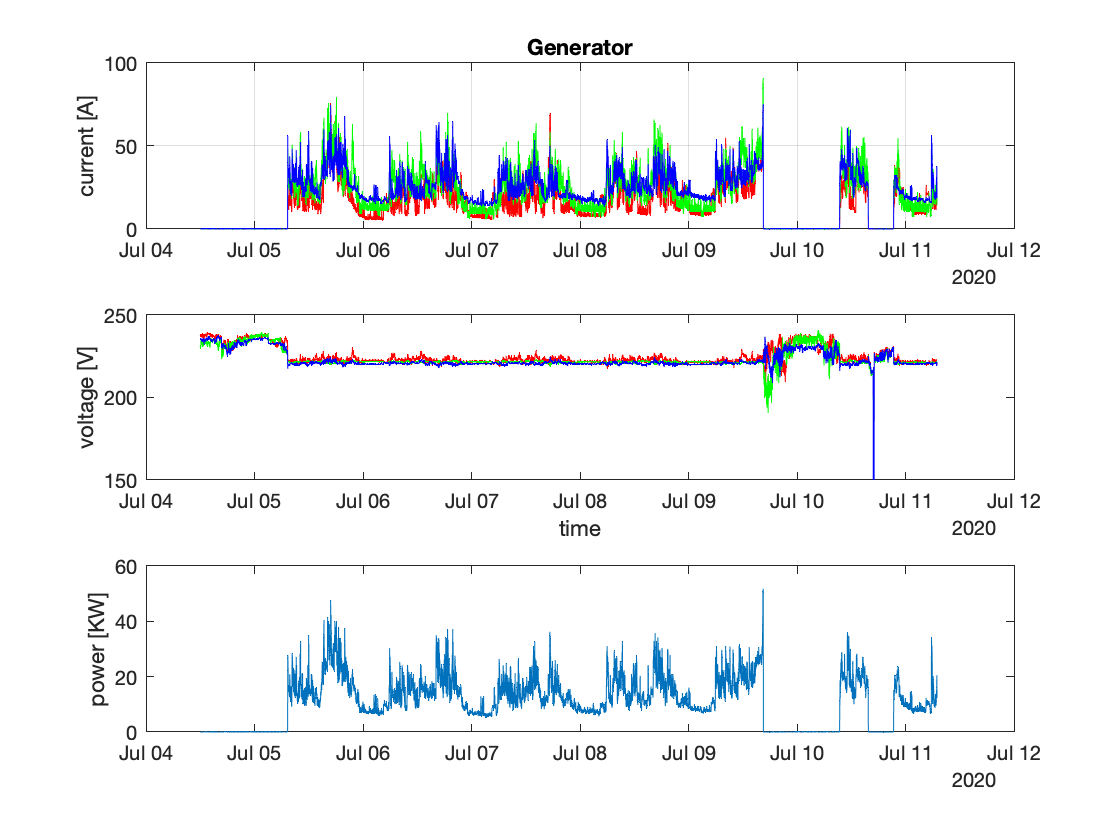

f12 = f_analyze_Overview(PEL2, "Generator");

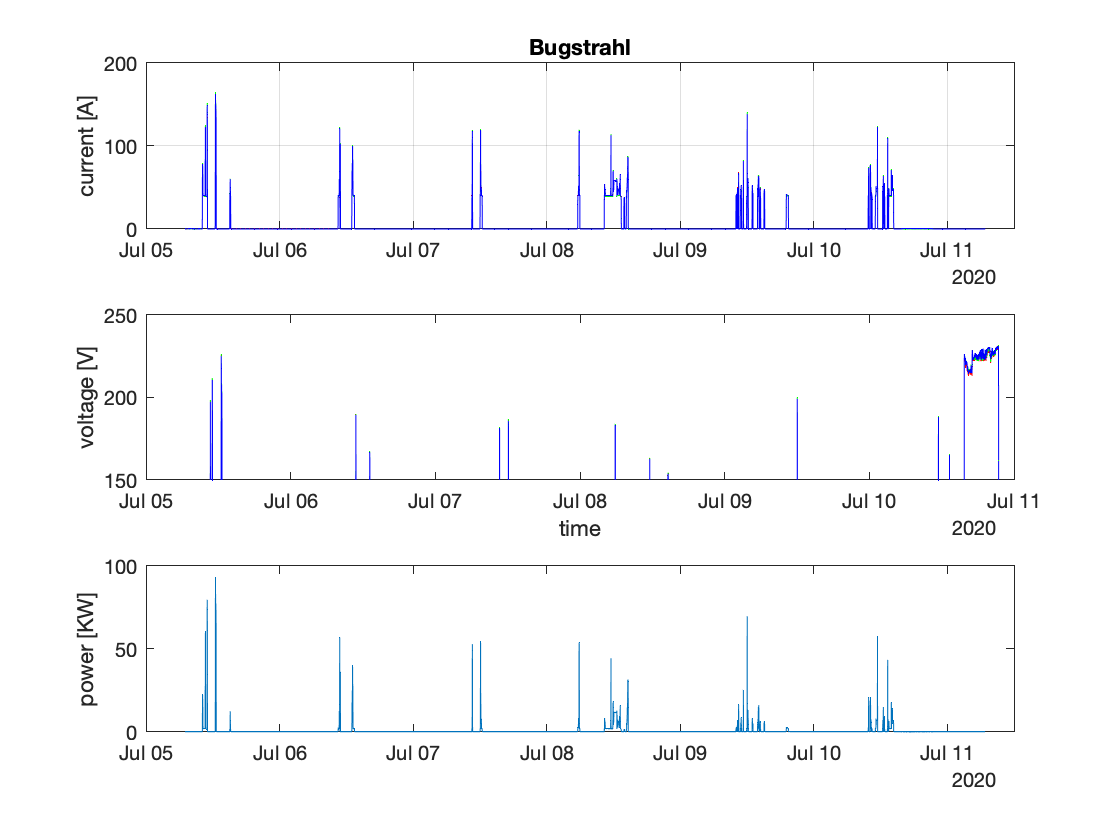

f13 = f_analyze_Overview(PEL3, "Bugstrahl");

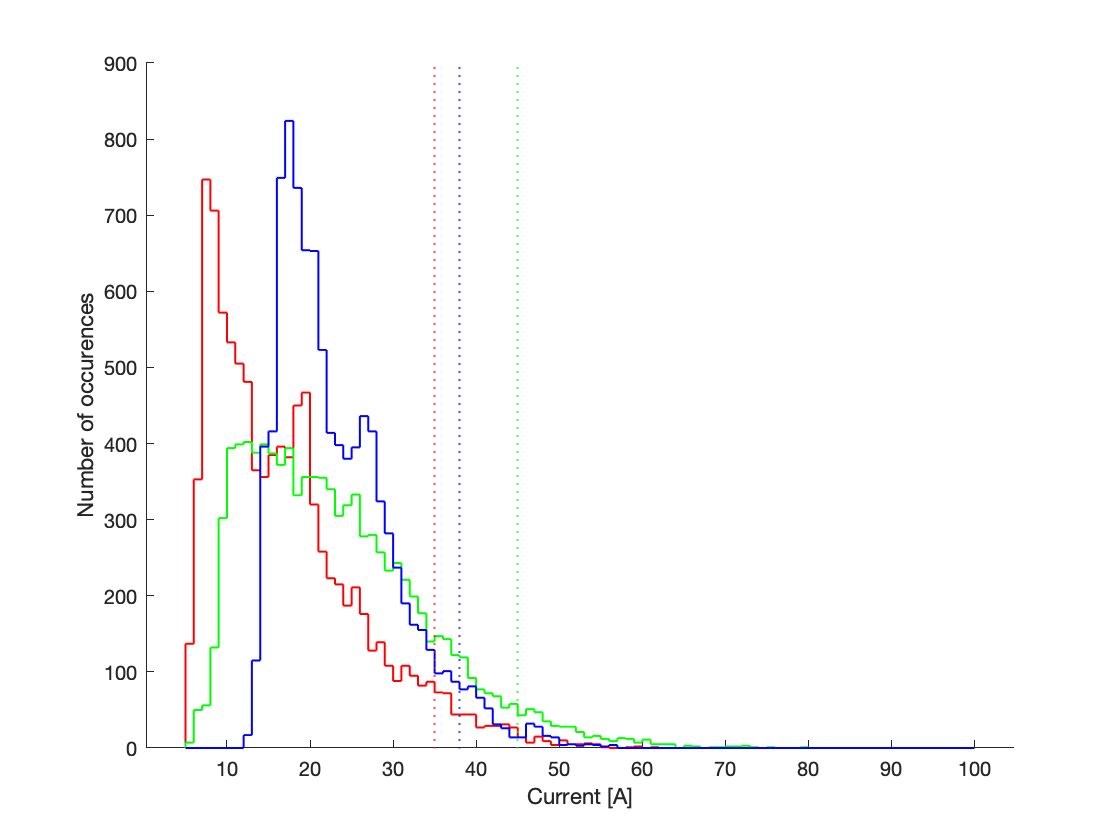

%% show histogramm
f21 = f_analyze_Histogram(PEL1, 2);

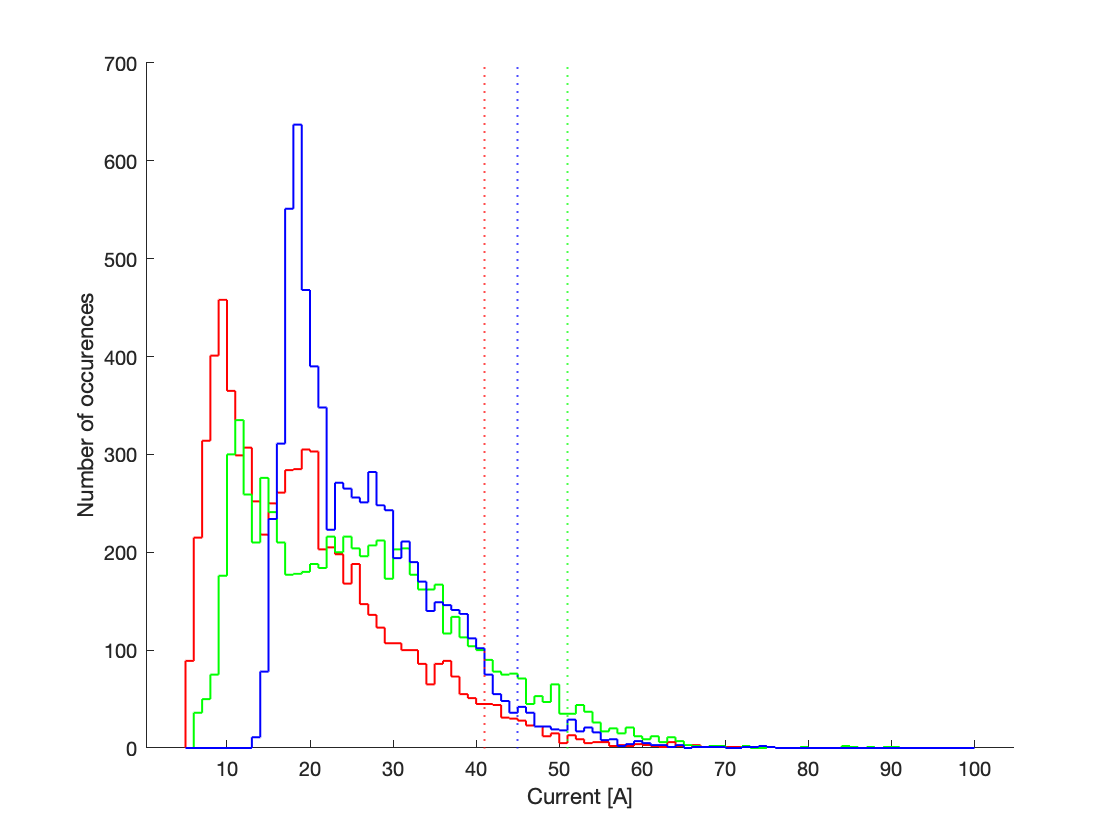

f22 = f_analyze_Histogram(PEL2, 2);

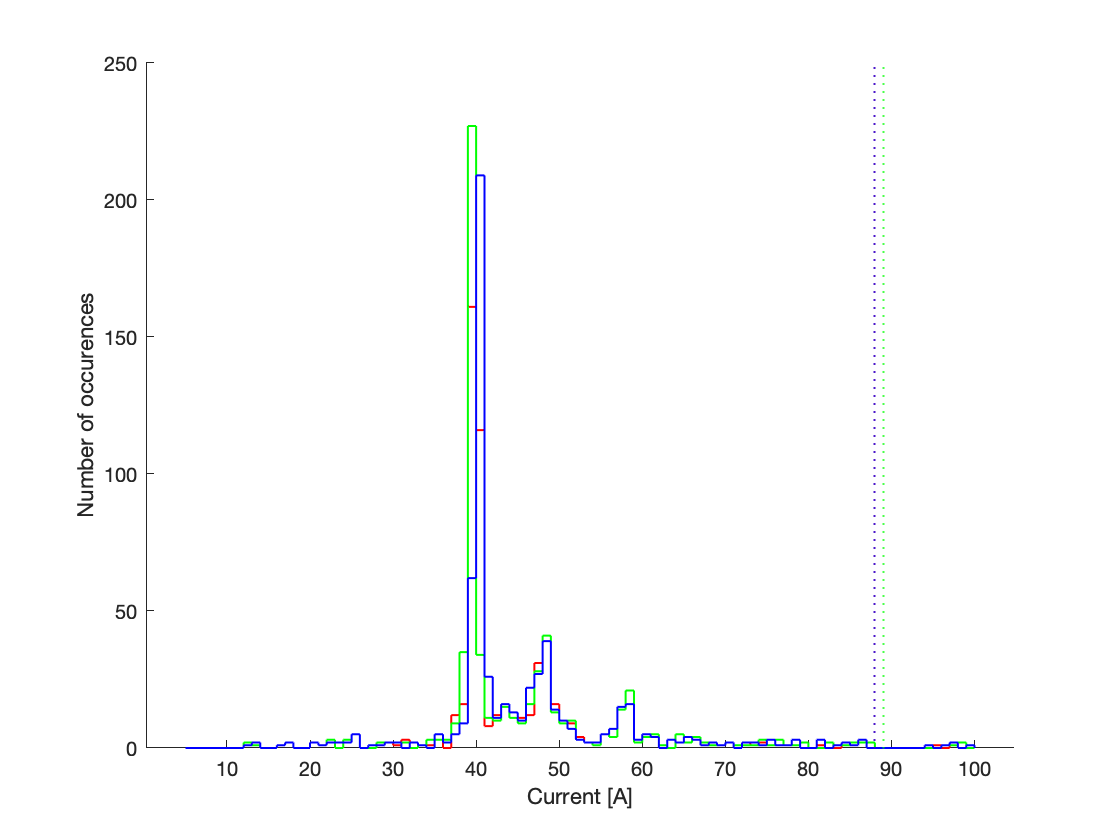

f23 = f_analyze_Histogram(PEL3, 2);

%% export graphics
exportgraphics(f11, 'images/Patria_electricity_Hauptverteiler.pdf','ContentType','vector')

exportgraphics(f12, 'images/Patria_electricity_Generator.pdf','ContentType','vector')

exportgraphics(f13, 'images/Patria_electricity_Bugstrahl.pdf','ContentType','vector')


exportgraphics(f21, 'images/Patria_power_histogram_Hauptverteiler.pdf','ContentType','vector')

exportgraphics(f22, 'images/Patria_power_histogram_Generator.pdf','ContentType','vector')

exportgraphics(f23, 'images/Patria_power_histogram_Bugstrahl.pdf','ContentType','vector')

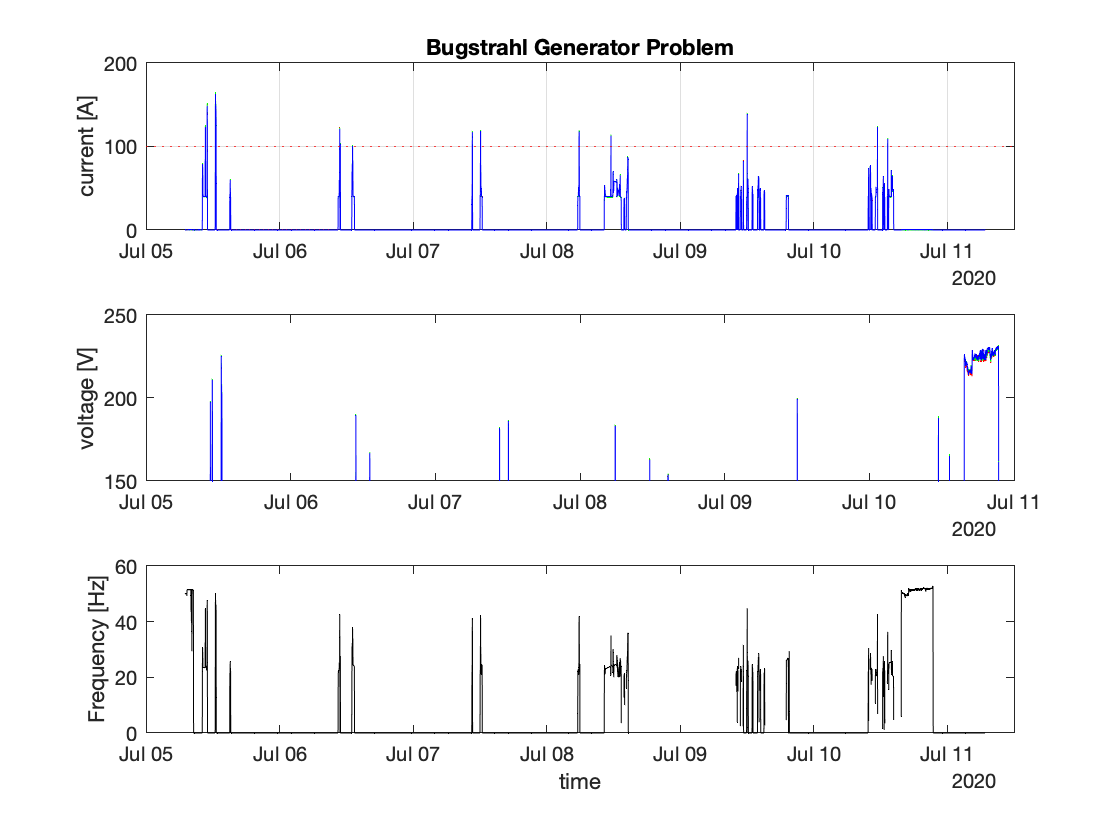

%% Bugstrahl Generator Problem
dataE = PEL3;
f3 = figure('Name', 'Problems_Bugstrahlgenerator');
subplot(311)
plot(dataE.Datum, dataE.I11min, 'r', dataE.Datum, dataE.I21min, 'g', dataE.Datum, dataE.I31min, 'b')
grid;
title('Bugstrahl Generator Problem')
% ylim([0 150])
ylabel('current [A]')
yline(100, 'r:')

subplot(312)
plot(dataE.Datum, dataE.V11min, 'r', dataE.Datum, dataE.V21min, 'g', dataE.Datum, dataE.V31min, 'b')
ylim([150 250])
ylabel('voltage [V]')

subplot(313)
plot(dataE.Datum, dataE.FHz1min, 'k')
ylabel('Frequency [Hz]')
xlabel('time')

exportgraphics(f3, 'images/Patria_Problems_Bugstrahlgenerator.pdf','ContentType','vector')

FROM = datetime('06.07.2020', 'InputFormat', 'dd.MM.yyyy');
TO = datetime('08.07.2020', 'InputFormat', 'dd.MM.yyyy');
df = data(timerange(FROM,TO),:);

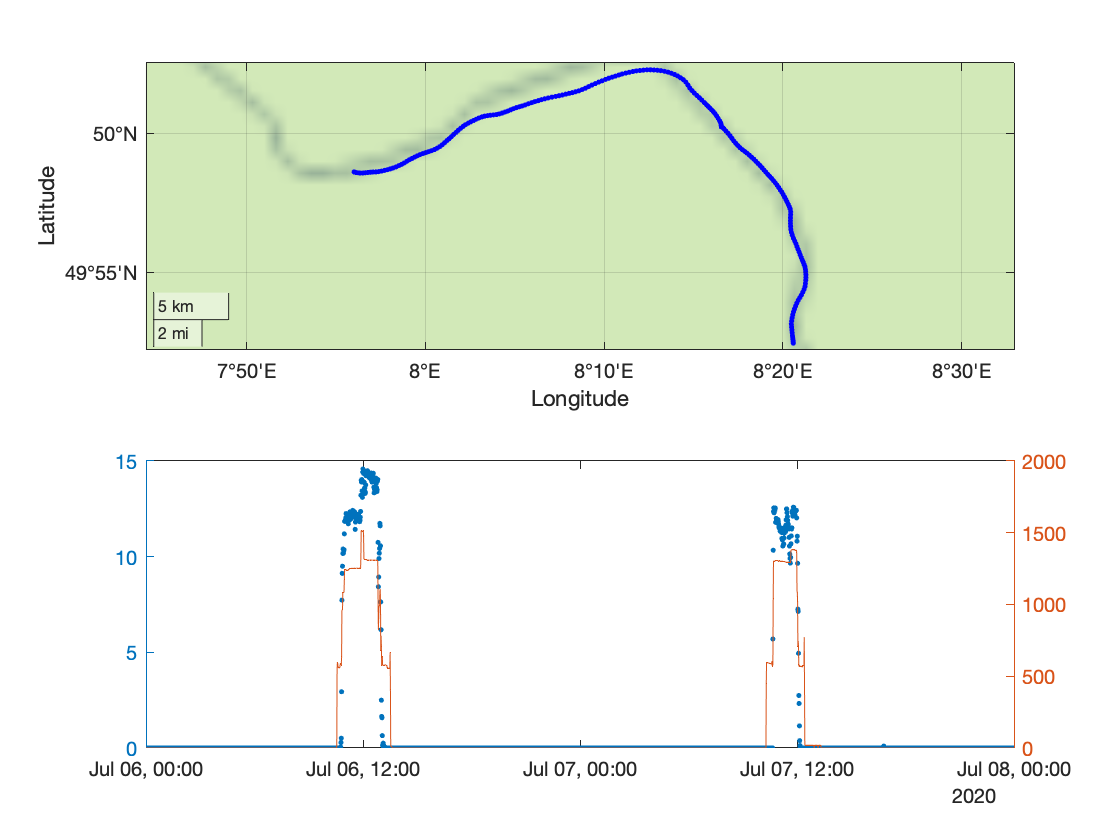

%% Ship movement
f = figure('Name', 'GPS and Motor');
subplot(211)
geoplot(df.Latitudedegrees, df.Longitudedegrees, 'b.', 'LineWidth', 0.5);
% geobasemap streets
% geobasemap satellite
% geobasemap landcover
geobasemap bluegreen
%geobasemap darkwater

subplot(212)
yyaxis right
plot(df.Date, df.rpm)
ylim([0 2000])

yyaxis left
plot(df.Date, df.Speedkmh,'.', 'linewidth', 0.1)
hold off

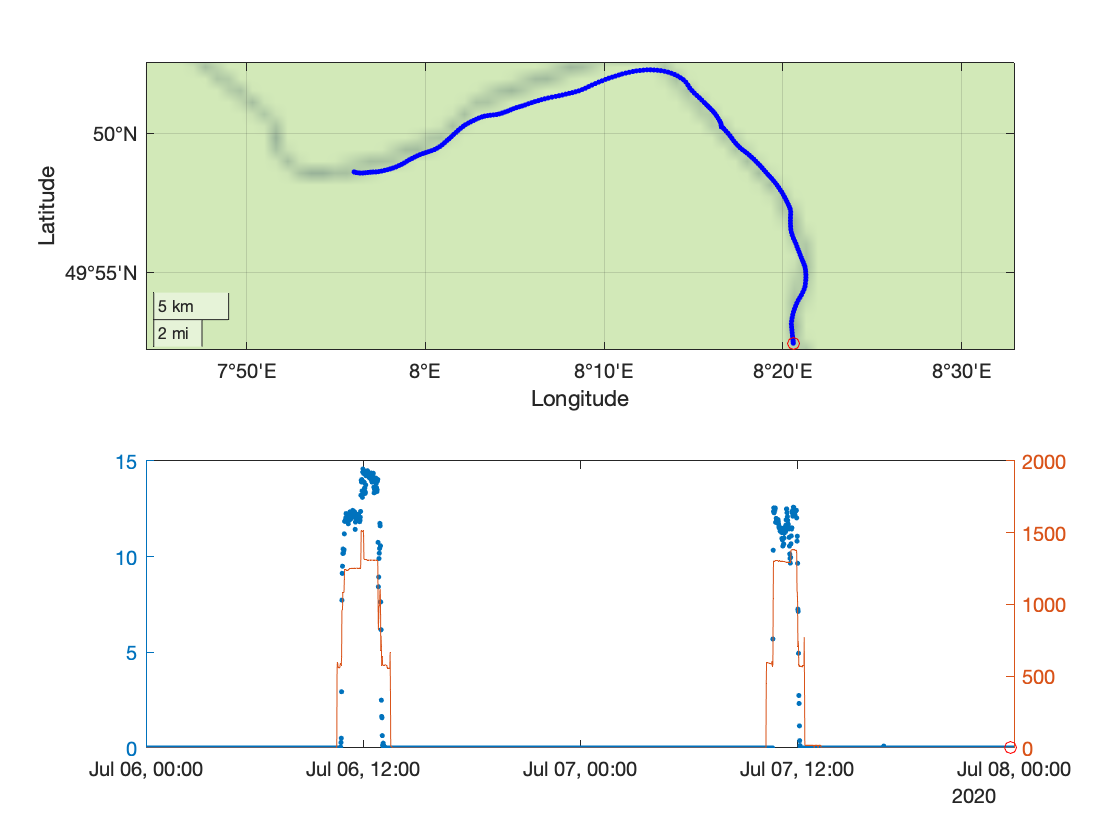

%% Animation
for i=1:10:height(df)
    if exist('h1', 'var')
        delete(h1)
    end
    if exist('h2', 'var')
        delete(h2)
    end

    figure(f)
    subplot(211)
    hold on
    h1 = geoplot(df.Latitudedegrees(i), df.Longitudedegrees(i), 'ro', 'LineWidth', 0.5);
    hold off
    drawnow
    
    subplot(212)
    hold on
    h2 = plot(df.Date(i), df.Speedkmh(i),'ro');
    hold off
    drawnow
end

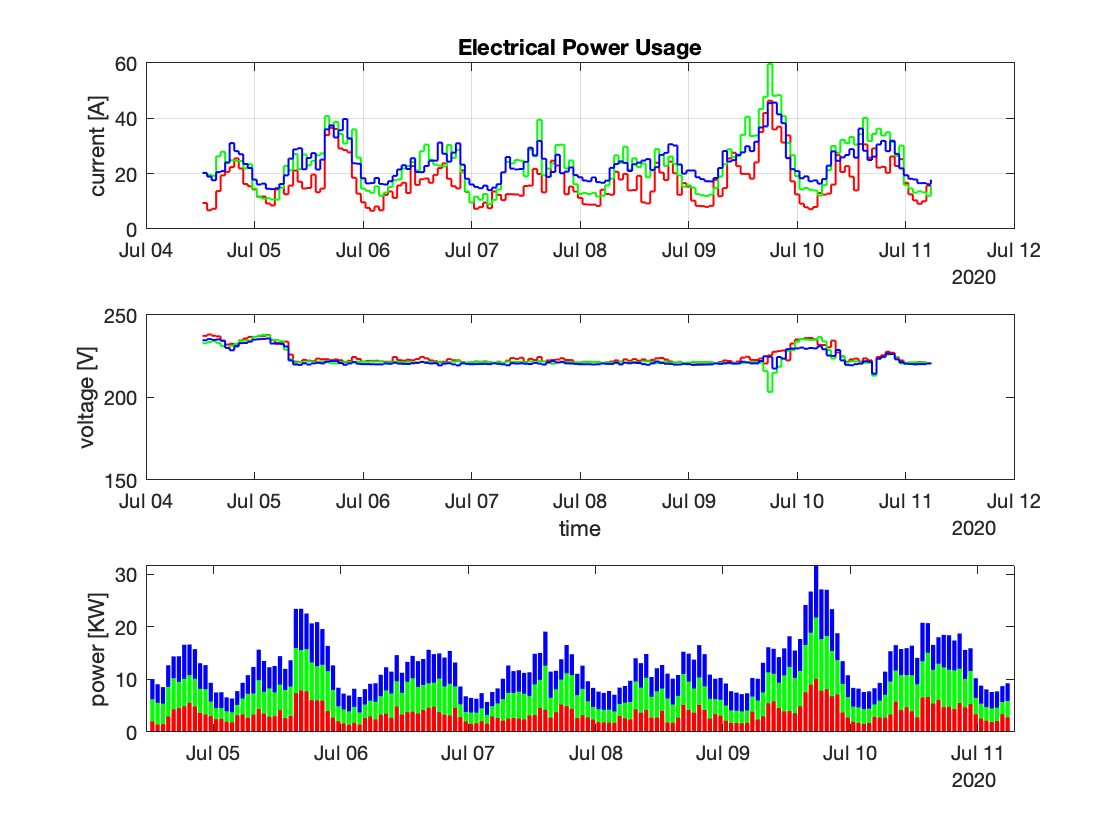

%% Comparison Downsampled data
dataE = PEL1;

dataE = f_analyze_Downsample(dataE, 60);
f1 = figure();
subplot(311)
b = stairs(dataE.Datum, [dataE.I11min, dataE.I21min, dataE.I31min], 'LineWidth', 1);
b(1).Color = 'r';
b(2).Color = 'g';
b(3).Color = 'b';
grid;
ylabel('current [A]')
title('Electrical Power Usage')

subplot(312)
b = stairs(dataE.Datum, [dataE.V11min, dataE.V21min, dataE.V31min], 'LineWidth', 1);
b(1).Color = 'r';
b(2).Color = 'g';
b(3).Color = 'b';
ylim([150 250])
ylabel('voltage [V]')
xlabel('time')

subplot(313)
b = bar(dataE.Datum, [dataE.P11min, dataE.P21min, dataE.P31min]/1e3, 'stacked');
b(1).FaceColor = 'r';
b(2).FaceColor = 'g';
b(3).FaceColor = 'b';
ylabel('power [KW]')

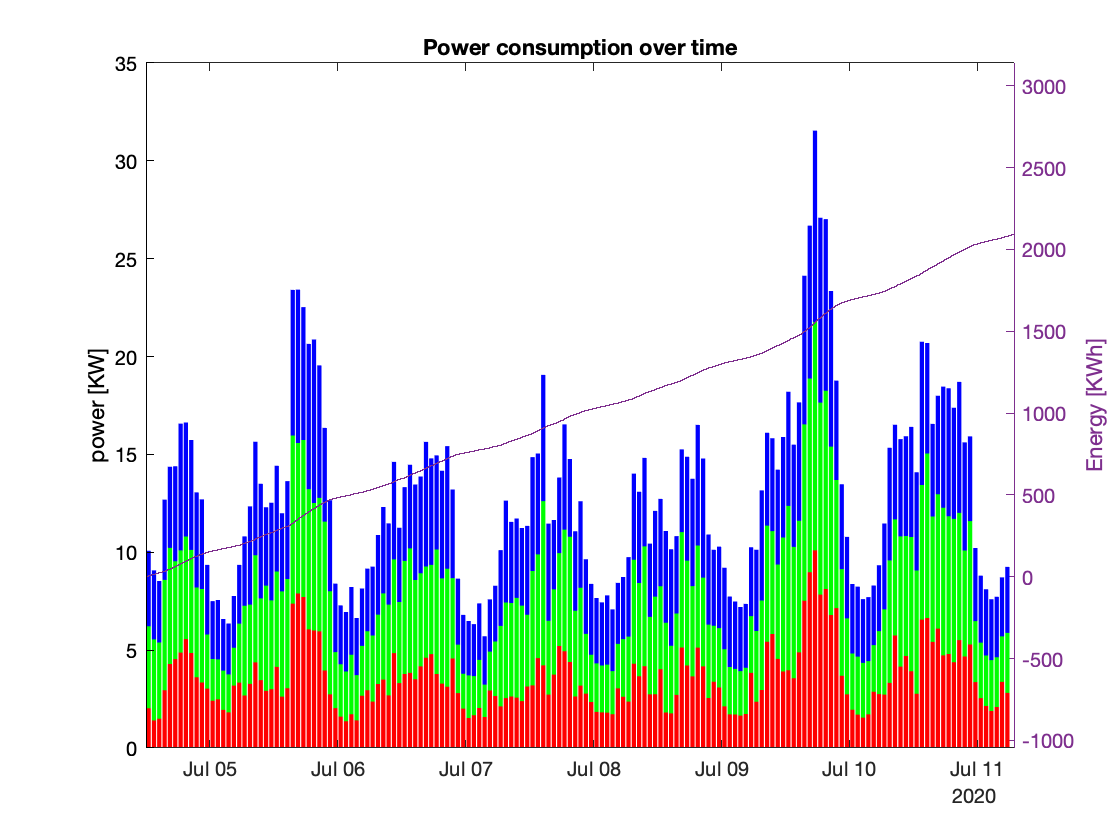


%% Power
dataE = f_analyze_Downsample(PEL1, 60);
f2 = figure('Name', 'Power Consumption MS Patria');
b = bar(dataE.Datum, [dataE.P11min, dataE.P21min, dataE.P31min]/1e3, 'stacked');
b(1).FaceColor = 'r';
b(2).FaceColor = 'g';
b(3).FaceColor = 'b';
title('Power consumption over time')
ylabel('power [KW]')
xlim([dataE.Datum(1), dataE.Datum(end)])
grid;

yyaxis right
stairs(PEL1.Datum, PEL1.EpWh1min)
ylabel('Energy [KWh]')
xlim([PEL1.Datum(1), PEL1.Datum(end)])
ylim([-0.5*PEL1.EpWh1min(end) 1.5*PEL1.EpWh1min(end)])
grid;

%% export graphics
exportgraphics(f1, 'images/Patria_electricity.pdf','ContentType','vector')

exportgraphics(f2, 'images/Patria_power_consumption.pdf','ContentType','vector')